# The sine-Gordon equation on a tetrahedron graph

Solves the wave equation $u_{tt} - \triangle u + \sin{u} = 0$ on a tetrahedron graph, using the leapfrog method

### Define the time and space limits and discretizations

L = 10;
nX = 40;
tfinal=5;
tprint = 0.25;

dt = 1/nX;
nSteps=tfinal/dt;
nSkip=tprint/dt;
t=0:tprint:tfinal;

### Set up the quantum graph

Phi = solidTemplates('tetrahedron','nX',nX,'L',L);
A = Phi.explicitLaplacian;

### Define the initial conditions

Recall that the leapfrog method requires the solution be given at times $t=0$ and $t=dt$. When the solution is a traveling wave, as here, we just use the (almost) exact solution at the two times.  If we are given the ordinary intial conditons of $u(x,0)= u_0(x)$ and $u_t(x,0)= v_0(x)$, then we may define the approximate solution at $t=dt$ using a second order Taylor approximation to be $u_1(x) = u_0(x) + v_0(x)\Delta t + \triangle u_0 \frac{\Delta t^2}{2}$.

#### Define the solution at t = 0

c0 = 0.95;
f0 = @(x)4*atan(exp((x-L/2)/sqrt(1-c0^2)));
f1 = @(x)2*pi*ones(size(x));
Phi.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
u0 =Phi.graph2column;


#### Define the solution at t = dt

f0 = @(x)4*atan(exp((x-L/2-c0*dt)/sqrt(1-c0^2)));
Phi.applyFunctionsToAllEdges({f0,f0,f0,f1,f1,f1});
u1 = Phi.graph2column;

### Evolve using the leapfrog method

U=u0;
for k=2:nSteps
    u2 = u1 + (u1-u0) + dt^2*(A*u1 - sin(u1));
    u0 = u1;
    u1 = u2;
    if mod(k,nSkip)==0
        U=[U u1];
    end
end

### Animate the solution

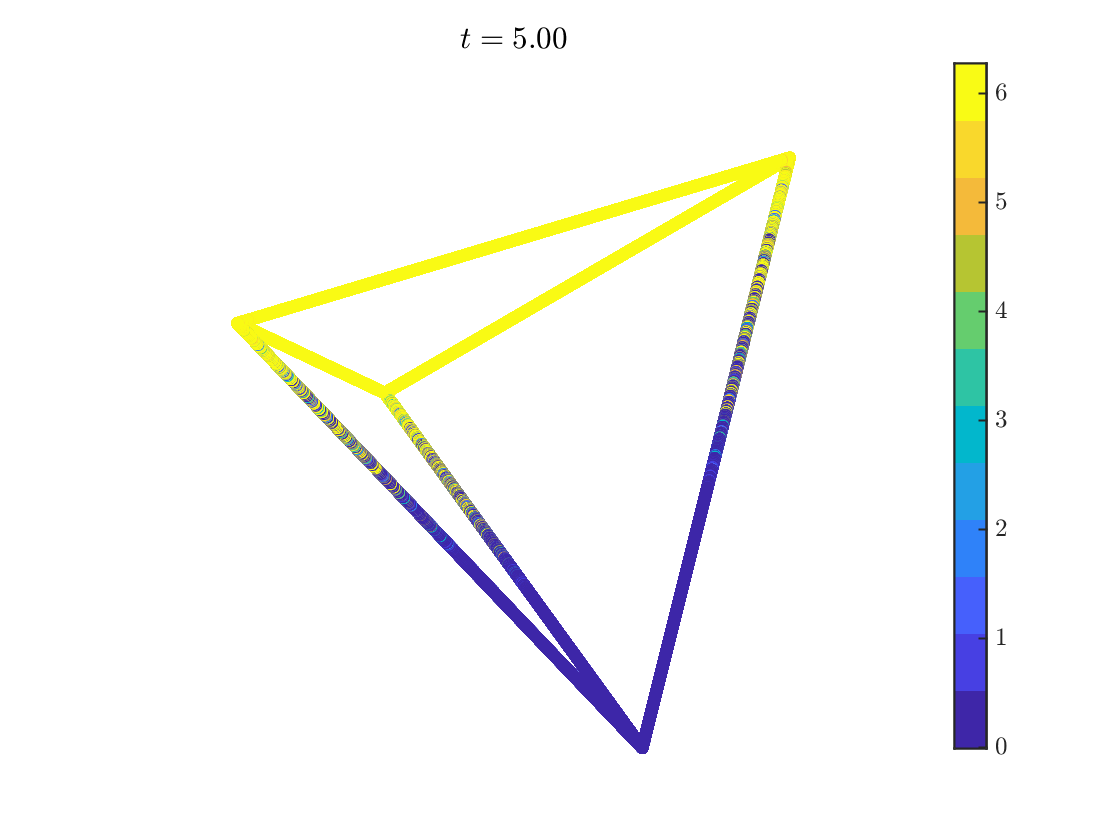

Phi.animatePDESolution(U,t)